%----------------------------------------------------
%-2.1 Reading the image
%----------------------------------------------------
pathImages_raw = 'images_raw/'

pathImages_raw = 'images_raw/'

pathImages_tiff = 'images_tiff/'

pathImages_tiff = 'images_tiff/'

filename = 'IMG_0596.CR2'

filename = 'IMG_0596.CR2'

%my_image = importdata(pathImages_raw + filename)
%my_image = Tiff('images_tiff/IMG_0596.tiff','r')
my_image = Tiff('cornell_box.tiff','r')

my_image =                   TIFF File: '/home/javier/Documents/MATLAB/assignment1/cornell_box.tiff'
                       Mode: 'r'
    Current Image Directory: 1
           Number Of Strips: 1
                SubFileType: Tiff.SubFileType.Default
                Photometric: Tiff.Photometric.MinIsBlack
                ImageLength: 3178
                 ImageWidth: 4770
               RowsPerStrip: 3178
              BitsPerSample: 16
                Compression: Tiff.Compression.None
               SampleFormat: Tiff.SampleFormat.UInt
            SamplesPerPixel: 1
        PlanarConfiguration: Tiff.PlanarConfiguration.Chunky
                Orientation: Tiff.Orientation.TopLeft


imgData = read(my_image)

imgData = 3178×4770 uint16 matrix
   1213   1500   1219   1511   1240   1481   1233   1432   1219   1463   1198   1478   1263   1530   1204   1503   1233   1538   1238   1562   1218   1527   1223   1571   1219   1550   1237   1518   1246   1478   1253   1554   1221   1544   1241   1543   1245   1509   1266   1521   1213   1537   1246   1501   1251   1496   1267   1544   1271   1535
   1531   1316   1513   1306   1490   1327   1452   1250   1450   1287   1531   1274   1485   1301   1536   1259   1521   1296   1551   1271   1496   1235   1502   1313   1477   1268   1545   1288   1580   1264   1502   1271   1562   1299   1561   1274   1543   1292   1519   1317   1547   1308   1490   1325   1509   1298   1541   1299   1551   1302
   1227   1497   1272   1479   1254   1507   1260   1473   1183   1453   1225   1515   1251   1460   1255   1514   1295   1543   1246   1514   1313   1473   1288   1593   1254   1536   1249   1538   1266   1547   1231   1490   1304   1586   1289   1522   1251   15

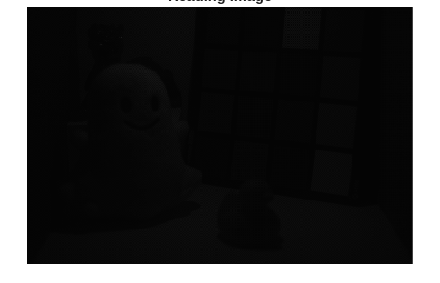

imshow(imgData)
title('Reading Image');

%----------------------------------------------------
%-2.1 Reading the image information
%----------------------------------------------------
info = imfinfo('images_tiff/IMG_0596.tiff');
bitsPerSample = info.BitsPerSample;
w = info.Width;
h = info.Height;

fprintf('Bits per sample: %s\n', num2str(bitsPerSample));

Bits per sample: 16


fprintf('Width: %s\n', num2str(w));

Width: 6024


fprintf('Height: %s\n', num2str(h));

Height: 4022


img_d = double(imgData);
%figure;
%imshow(img_d);
%title('Doble Image');

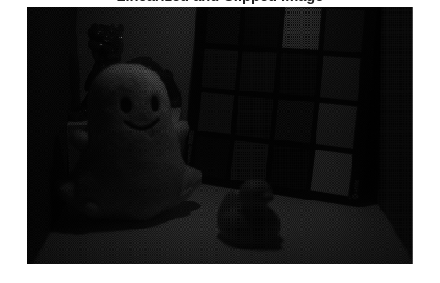

%----------------------------------------------------
%-2.2 Linearization
%----------------------------------------------------
dark_noise = 1023;
saturation = 15600;
I_linear = (img_d - dark_noise) / (saturation - dark_noise);
img_clip = clip(I_linear,0,1);
%figure;
%imshow(img_clip);
%title('Linearization Image');



%----------------------------------------------------
%-2.2 Linearization
%----------------------------------------------------
dark_noise = 1023;  % Dark noise threshold
saturation = 15600; % Saturation threshold

% Assuming 'img_d' is your input image (raw Bayer-filtered or any other)
I_linear = (img_d - dark_noise) / (saturation - dark_noise);  % Linearize the image

% Manually clip values outside the [0, 1] range
I_linear_clipped = max(min(I_linear, 1), 0);  % Clip values between 0 and 1

% Display the resulting image
figure;
imshow(I_linear_clipped);
title('Linearized and Clipped Image');

%----------------------------------------------------
%-3 Demosaicing
%----------------------------------------------------
%- i) nearest neighbor 
%- 
%----------------------------------------------------

%*******************
corner_2x2 = img_clip(1:2,1:2);
disp(corner_2x2)

    0.0130    0.0327
    0.0348    0.0201



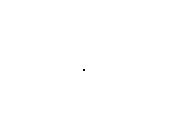


%We identify BGGR for the new image.
figure;
imshow(corner_2x2);

%*******************

%**************************************
%- i) Interpolation: nearest neighbor
%**************************************
% Separate the color channels based on the Bayer pattern
% RGGB pattern

% Extract the Blue, Green, and Red channels for BGGR Bayer pattern
[height, width] = size(img_clip);  % Get the dimensions of the image

% Separate the color channels based on the BGGR Bayer pattern
blue_channel = zeros(height,width)

blue_channel =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0    

blue_channel(1:2:end, 1:2:end) = img_clip(1:2:end, 1:2:end);  % Blue: odd rows, even columns
green_channel = zeros(height,width)

green_channel =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0   

green_channel(1:2:end, 2:2:end) = img_clip(1:2:end, 2:2:end); % Green: even rows, odd columns
green_channel(2:2:end, 1:2:end) = img_clip(2:2:end, 1:2:end); % Green: odd rows, even columns
red_channel = zeros(height,width)

red_channel =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     

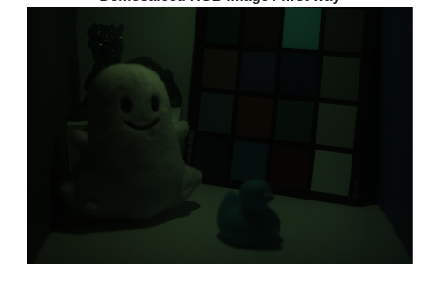

red_channel(2:2:end, 2:2:end) = img_clip(2:2:end, 2:2:end);   % Red: even rows, odd columns


%% 1. Fill Blue Channel (Known at 1,1)
% Copy the value at (1,1) to the rest of the 2x2 block
blue_full = blue_channel;
blue_full(1:2:end, 2:2:end) = blue_full(1:2:end, 1:2:end); % Copy Right
blue_full(2:2:end, 1:2:end) = blue_full(1:2:end, 1:2:end); % Copy Down
blue_full(2:2:end, 2:2:end) = blue_full(1:2:end, 1:2:end); % Copy Diagonal

%% 2. Fill Red Channel (Known at 2,2)
% Copy the value at (2,2) to the rest of the 2x2 block
red_full = red_channel;
red_full(1:2:end, 1:2:end) = red_full(2:2:end, 2:2:end); % Copy Diagonal Up
red_full(1:2:end, 2:2:end) = red_full(2:2:end, 2:2:end); % Copy Up
red_full(2:2:end, 1:2:end) = red_full(2:2:end, 2:2:end); % Copy Left

%% 3. Fill Green Channel (Known at 1,2 and 2,1)
% Since we have two greens, we just fill the missing spots with the nearest one
green_full = green_channel;
green_full(1:2:end, 1:2:end) = green_full(1:2:end, 2:2:end); % Top-left gets Top-right
green_full(2:2:end, 2:2:end) = green_full(2:2:end, 1:2:end); % Bottom-right gets Bottom-left



img_rgb = cat(3,red_full,green_full,blue_full);
% Display the RGB image
figure;
imshow(img_rgb);
title('Demosaiced RGB Image / first way');

%TODO: complete / only implement one of them
%----------------------------------------------------
%-3 Demosaicing
%----------------------------------------------------
%- ii) bilinear interpolation 
%----------------------------------------------------

%TODO: complete
%----------------------------------------------------
%-4 White balancing
%----------------------------------------------------
%- i)  the white world white balancing
%----------------------------------------------------

%TODO: complete
%----------------------------------------------------
%-4 White balancing
%----------------------------------------------------
%- ii)   gray world white balancing
%----------------------------------------------------

%TODO: complete / 1 point each
%----------------------------------------------------
%-5 Denoising
%----------------------------------------------------
%- i) mean filtering
%----------------------------------------------------

%TODO: complete / 1 point each
%----------------------------------------------------
%-5 Denoising
%----------------------------------------------------
%- ii) median filtering
%----------------------------------------------------

%TODO: complete / 1 point each
%----------------------------------------------------
%-5 Denoising
%----------------------------------------------------
%- iii) Gaussian filtering.
%----------------------------------------------------

%TODO: complete / 1 point each
%----------------------------------------------------
%-6 Color balance
%----------------------------------------------------
%- 
%---------------------------------------------------- 